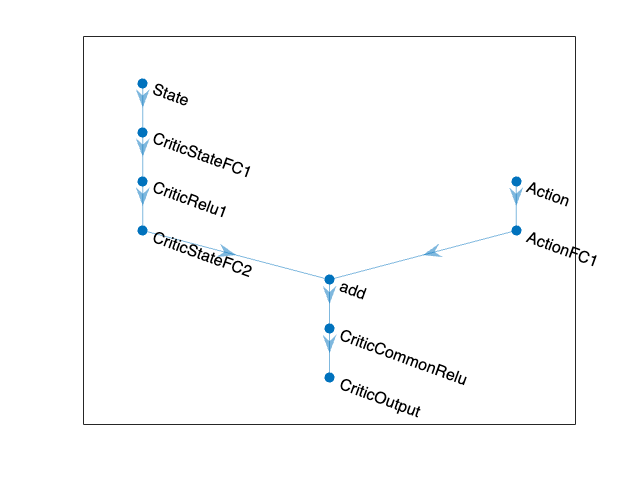

clc;clear;close all;
open_system('rlBallandPlate')
obsInfo = rlNumericSpec([3 1],...
    'LowerLimit',[-inf -inf -inf ]',...
    'UpperLimit',[ inf  inf inf]');

numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([3 1]);
numActions = actInfo.Dimension(1);
env = rlSimulinkEnv('rlBallandPlate','rlBallandPlate/RL Agent',...
    obsInfo,actInfo);
env.ResetFcn = @(in)localResetFcn(in);
Ts = 1;
Tf = 40;
rng(0)
statePath = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(350,'Name','CriticStateFC1')
    tanhLayer('Name','CriticRelu1')
    fullyConnectedLayer(350,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([numActions 1 1],'Normalization','none','Name','Action')
    fullyConnectedLayer(350,'Name','ActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    tanhLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'ActionFC1','add/in2');
figure
plot(criticNetwork)

criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);
critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

actorNetwork = [
    imageInputLayer([numObservations 1 1],'Normalization','none','Name','State')
    fullyConnectedLayer(350,'Name','ActorFC1')
    tanhLayer('Name','ActorRelu1') 
    fullyConnectedLayer(350,'Name','ActorFC2')
    tanhLayer('Name','ActorRelu2') 
    fullyConnectedLayer(3,'Name','Action')
   % reluLayer('Name','ActorRelu3')     
    %fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-05,'GradientThreshold',1);

actor = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6);
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

%maxepisodes = 459;
maxepisodes = 480;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',999);

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);

end

%validation
resp={};
tgt=[];
times= {};
time_gains={};
kp={};
ki={};
kd={};
%val_vals= -1.5+ 1.5 *rand(1,10);
val_vals = 1;

for i=1: length(val_vals)
    h = val_vals(i)
    blk = sprintf('rlBallandPlate/Reference');
    set_param(blk,'Value',num2str(h));
    simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
    experiences = sim(env,agent,simOpts);
    tgt=[tgt experiences.SimulationInfo.Desired];
    resp{end+1}= experiences.SimulationInfo.Actual;
    times{end+1}= experiences.SimulationInfo.tout;
    kp{end+1}= experiences.SimulationInfo.Kp.signals.values;
    ki{end+1}= experiences.SimulationInfo.Ki.signals.values;
    kd{end+1}= experiences.SimulationInfo.Kd.signals.values;
    time_gains{end+1}= experiences.SimulationInfo.Kp.time;
    
end

h = 1

function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('rlBallandPlate/Reference');
h =1;
%h= -1.5+1.5*(rand(1,1));

in = setBlockParameter(in,blk,'Value',num2str(h));


end


